# Operating point


V_vsc_mag=1;P_t=P_aero_0;%x_sys=0.8768 % mistake
delta_vsc_0=asin((x_sys*P_t/V_vsc_mag))

delta_vsc_0 = 0.6940

delta_vsc_0*180/pi

ans = 39.7610

% Q_t=-(V_vsc_mag^2-cos(delta_vsc_0))/x_sys
Q_t = -0.12

Q_t = -0.1200


v_D0_g = 1;
v_Q0_g = 0;

% V_vsc
% V_vsc=V_vsc_mag*(cos(delta_vsc_0)+1i*sin(delta_vsc_0))
% v_D0_vsc =real(V_vsc), v_Q0_vsc = imag(V_vsc)

% I_vsc
% i_D0_vsc = -(r_sys*v_D0_g - r_sys*v_D0_vsc + v_Q0_g*x_sys - v_Q0_vsc*x_sys)/(r_sys^2 + x_sys^2)
% i_Q0_vsc = -(r_sys*v_Q0_g - r_sys*v_Q0_vsc - v_D0_g*x_sys + v_D0_vsc*x_sys)/(r_sys^2 + x_sys^2)

% I_vsc=conj((P_t+1i*Q_t))/(V_vsc_mag*(cos(delta_vsc_0)-1i*sin(delta_vsc_0)))
% i_D0_vsc = real(I_vsc), i_Q0_vsc = imag(I_vsc)

% angle(I_vsc);ans*180/pi
% abs(I_vsc)
% 
% 
% V_t=V_vsc_mag*[cos(delta_vsc_0); sin(delta_vsc_0)]+[r_f -l_f;r_f l_f]*[i_D0_vsc; i_Q0_vsc]
% delta_t=atan(V_t(2)/V_t(1)); delta_t*180/pi
% V_t_mag=abs(V_t)
% v_D0_t = V_t(1), v_Q0_t = V_t(2)

% Operating point from non-linear model
v_D0_vsc =0.8215, v_Q0_vsc = 0.5597

v_D0_vsc = 0.8215

v_Q0_vsc = 0.5597

i_D0_vsc = 2.145e5/Ibase_lv, i_Q0_vsc =2.178789e5/Ibase_lv%i_D0_grid = 0.474, i_Q0_grid =0.3762

i_D0_vsc = 0.4316

i_Q0_vsc = 0.4384

i_D0_grid = 0.474, i_Q0_grid =0.3762

i_D0_grid = 0.4740

i_Q0_grid = 0.3762

v_D0_t = 0.7922, v_Q0_t = 0.5917

v_D0_t = 0.7922

v_Q0_t = 0.5917


2.145e5/Ibase_lv

ans = 0.4316

theta_0_vsc = 0.8354107558;
Delta_vsc_0 = 1*(0.5981)

Delta_vsc_0 = 0.5981

init_v_DQ_t = [0, v_D0_t, v_Q0_t]

init_v_DQ_t =          0    0.7922    0.5917



% v_dq0_t = [cos(Delta_vsc_0) -sin(Delta_vsc_0); sin(Delta_vsc_0) cos(Delta_vsc_0)]*[v_D0_t v_Q0_t]'


% dq/DqQ transformation matrices
P_meas = [v_D0_vsc v_Q0_vsc i_D0_vsc i_Q0_vsc] 

P_meas =     0.8215    0.5597    0.4316    0.4384


Q_meas = [v_Q0_vsc -v_D0_vsc -i_Q0_vsc i_D0_vsc]

Q_meas =     0.5597   -0.8215   -0.4384    0.4316



v_d_t = [-v_Q0_t*sin(Delta_vsc_0)+v_D0_t*cos(Delta_vsc_0) cos(Delta_vsc_0) sin(Delta_vsc_0) ];
v_q_t = [v_D0_t*cos(Delta_vsc_0)+v_Q0_t*sin(Delta_vsc_0) -sin(Delta_vsc_0) cos(Delta_vsc_0) ];

v_d_vsc = [-v_Q0_vsc*sin(Delta_vsc_0)+v_D0_vsc*cos(Delta_vsc_0) cos(Delta_vsc_0) sin(Delta_vsc_0) ];
v_q_vsc = [v_D0_vsc*cos(Delta_vsc_0)+v_Q0_vsc*sin(Delta_vsc_0) -sin(Delta_vsc_0) cos(Delta_vsc_0) ];
i_d_vsc = [-i_Q0_vsc*sin(Delta_vsc_0)+i_D0_vsc*cos(Delta_vsc_0) cos(Delta_vsc_0) sin(Delta_vsc_0) ];
i_q_vsc = [i_D0_vsc*cos(Delta_vsc_0)+i_Q0_vsc*sin(Delta_vsc_0) -sin(Delta_vsc_0) cos(Delta_vsc_0) ];
i_d_grid = [-i_Q0_grid*sin(Delta_vsc_0)+i_D0_grid*cos(Delta_vsc_0) cos(Delta_vsc_0) sin(Delta_vsc_0) ];
i_q_grid = [i_D0_grid*cos(Delta_vsc_0)+i_Q0_grid*sin(Delta_vsc_0) -sin(Delta_vsc_0) cos(Delta_vsc_0) ];
% T_vsc's
T_vDQ_dq = [v_d_vsc; v_q_vsc]

T_vDQ_dq =     0.3637    0.8264    0.5631
    0.9940   -0.5631    0.8264


T_iDQ_dq = [i_d_vsc; i_q_vsc]

T_iDQ_dq =     0.1098    0.8264    0.5631
    0.6035   -0.5631    0.8264


T_igridDQ_dq = [i_d_grid; i_q_grid]

T_igridDQ_dq =     0.1799    0.8264    0.5631
    0.6035   -0.5631    0.8264


T_vDQ_t_dq = [v_d_t; v_q_t]

T_vDQ_t_dq =     0.3215    0.8264    0.5631
    0.9879   -0.5631    0.8264




T_PQ_meas = [P_meas; Q_meas]

T_PQ_meas =     0.8215    0.5597    0.4316    0.4384
    0.5597   -0.8215   -0.4384    0.4316


v_dq_vsc0 = T_vDQ_dq*[0; v_D0_vsc; v_Q0_vsc]

v_dq_vsc0 =     0.9940
   -0.0000


v_dq0_t  = T_vDQ_t_dq*init_v_DQ_t';
% v_d0_t = v_dq0_t(1)
% v_q0_t = v_dq0_t(2)
% Non linear OP
v_d0_t = 0.9878

v_d0_t = 0.9878

v_q0_t = 0.0429

v_q0_t = 0.0429

atan(v_q0_t/v_d0_t),atan(v_Q0_t/v_D0_t)

ans = 0.0434

ans = 0.6415

% T_vsc's inverse
v_D_t = [-v_q0_t*sin(Delta_vsc_0)-v_d0_t*cos(Delta_vsc_0) cos(Delta_vsc_0) -sin(Delta_vsc_0) ]

v_D_t =    -0.8405    0.8264   -0.5631


v_Q_t = [+v_d0_t*cos(Delta_vsc_0)-v_q0_t*sin(Delta_vsc_0) sin(Delta_vsc_0) cos(Delta_vsc_0) ]

v_Q_t =     0.7922    0.5631    0.8264


T_vdq_DQ = [v_D_t; v_Q_t]

T_vdq_DQ =    -0.8405    0.8264   -0.5631
    0.7922    0.5631    0.8264


## p/angle controller


% 
% k_d_vsm= 70
% % 
% H_vsm = 3
T_vsm = tf([omega_nom/(2*H_vsm*l_f/omega_nom)*cos(delta_vsc_0)],[1 k_d_vsm/(2*H_vsm) omega_nom/(2*H_vsm*l_f/omega_nom)*cos(delta_vsc_0)])

T_vsm =
 
          1.198e05
  ------------------------
  s^2 + 11.67 s + 1.198e05
 
Continuous-time transfer function.
Model Properties



G_vsm = omega_nom/(2*H_vsm*s+k_d_vsm)

G_vsm =
 
   314.2
  --------
  6 s + 70
 
Continuous-time transfer function.
Model Properties



zeta_vsm = k_d_vsm/H_vsm*sqrt(2*H_vsm*x_sys/omega_nom)      

zeta_vsm = 3.3293

nf_vsm = sqrt(omega_nom/(2*H_vsm*x_sys))

nf_vsm = 7.0085

% step(T_vsm*0.1)




## q controller droop


% ki_q = 2*pi*10
% k_p_q_vsm = -0.05

% open loop

%closed loop 
T_q_vsm = tf([ki_q*k_p_q_vsm/x_sys],[1 ki_q+k_p_q_vsm*ki_q/x_sys])

T_q_vsm =
 
   -14.74
  ---------
  s + 299.4
 
Continuous-time transfer function.
Model Properties



%open loop Q_grid -> delta V_d_ref
G_qdroop = tf([ki_q*k_p_q_vsm],[1 ki_q])

G_qdroop =
 
   -15.71
  ---------
  s + 314.2
 
Continuous-time transfer function.
Model Properties


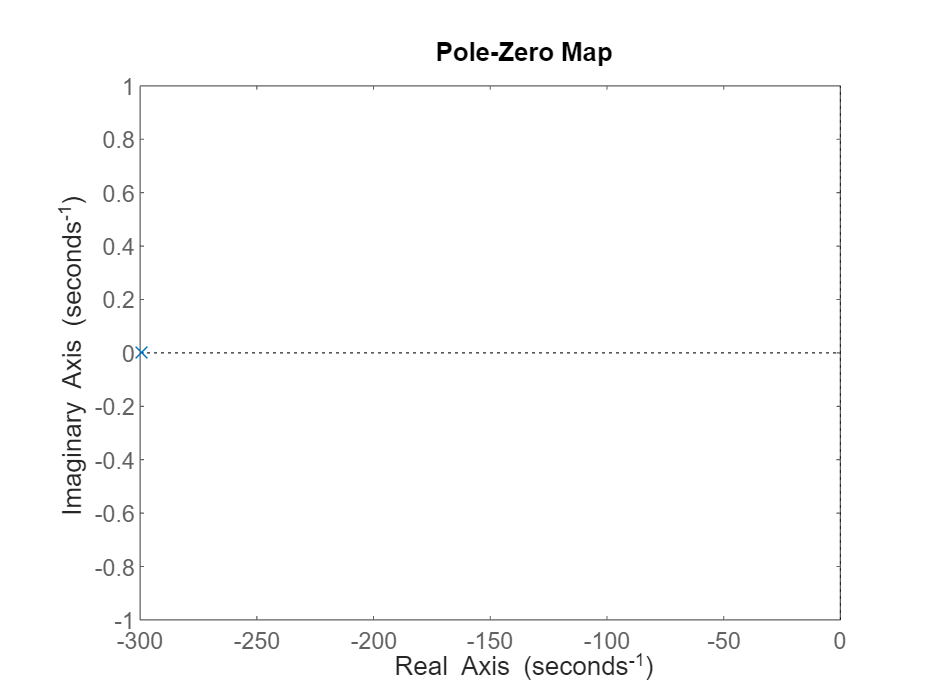


% step(T_q_vsm)
% step(T_e_vsm)

pzmap(T_q_vsm)

## current control

% s = tf('s')
% ti = 5/f_sw
% G_plant = 1/(s*l_f/omega_nom+r_f)
% kp = (l_f/omega_nom)/ti
% ki = r_f/ti
% G_cc = (kp*s+ki)/s
% T_cc = G_plant*G_cc/(1+G_plant*G_cc)
% 
% tf2ss([kp ki], [1 0])
% margin(G_plant*G_cc)
% step(T_cc)
% bode(T_cc,1/(ti*s+1))
% legend('T_cc', 'T_cc_approx')
% bode(((0.01*s+1)/0.01)/(1+(0.01*s+1)/0.01)) 
% 
% 
% % G_plant = 1/(s*l_f/omega_nom+r_f)
% % G_grid_plant = 1/(s*x_sys/omega_nom+r_grid)
% % dq tf 
% i_DQ_plant = [s*l_f/omega_nom+r_f -l_f;
%               l_f s*l_f/omega_nom+r_f]
% i_dq_ctrl = eye(2,2)*G_cc
%  i_dq_ff = [0 -l_f;
%             l_f 0]
% i_DQ_grid = [s*x_sys/omega_nom+r_grid -x_sys;
%               x_sys  s*x_sys/omega_nom+r_grid]

## voltage control



% z = 20
% asind((1-ti*z)/(1+ti*z)) % phase margin
% omega_c_vc = sqrt(z/ti)
% k_vc = (c_f/omega_nom)*omega_c_vc
% G_vc = k_vc*(s+z)/s
% %open
% G_forward_vc = k_vc/(ti*(c_f/omega_nom))*((s+z)/(s+1/ti))*1/s^2
% margin(G_forward_vc)
% % closed
% T_vc = k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2/(1+k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2)
%     step(T_vc)
%     pzmap(T_vc)
% 
%  v_DQ_plant = [s*c_f/omega_nom -c_f;
%                 c_f s*c_f/omega_nom]
%  v_dq_ctrl = eye(2,2)*G_vc
%  v_dq_ff = [0 -c_f;
%             c_f 0]

## Detailed dc voltage controller

% 
% c_dc =0.00666540000000 % pu  0.47 % aggregated
% % negative 1 is steady state wind power pu
% % cross over frequency is 20 rad/s
%     zigma_dc = 2*l_f*(1)/(3*1^2)
% k0 = 1.5
% G_dc_pre =-k0*2/c_dc*(zigma_dc*s+1)/(s^2*(0.01*s+1)) 
% margin(G_dc_pre)
% step(G_dc_pre/(1+G_dc_pre))
% 
% n0 = 1/(10^(-13/20));
% 
% a = 50; 
% asind((a-1)/(a+1)) % phase margin
% p = sqrt(a)*23;
% N = -n0*(s+p/a)/(s+p)
% bode(N,N*G_dc_pre)
% margin(N*G_dc_pre)
% step(G_dc_pre*N/(1+G_dc_pre*N))
% 
% G_dc = N*k0/s 
% G_dc_num = get(G_dc,'Numerator')
% G_dc_denom = get(G_dc,'Denominator')
% T_dc = -2/c_f*(zigma_dc*s+1)/s
% T_dc_num = get(T_dc,'Numerator')
% T_dc_denom = get(T_dc,'Denominator')

##  dc voltage controller TV

% 
% C_dc_TV = 0.3 % F
% V_dc
% % negative 1 is steady state wind power pu
% % cross over frequency is 20 rad/s
% 
% G_dc_pre =1/(C_dc*s*V_dc) 
% margin(G_dc_pre)
% % step(G_dc_pre/(1+G_dc_pre))
% 
% kp_dc = 0.78;
% ki_dc = 0.85;
% margin(G_dc_pre*G_dc)
% G_dc = 1*(kp_dc + ki_dc/s)
% 
% 
% % a = 50; 
% % asind((a-1)/(a+1)) % phase margin
% % p = sqrt(a)*23;
% % N = -n0*(s+p/a)/(s+p)
% % bode(N,N*G_dc_pre)
% % margin(N*G_dc_pre)
% % step(G_dc_pre*N/(1+G_dc_pre*N))
% step(G_dc_pre*G_dc/(1+G_dc_pre*G_dc)*K_TP)
% G_dc_num = get(G_dc,'Numerator')
% G_dc_denom = get(G_dc,'Denominator')
% T_dc = G_dc_pre
% T_dc_num = get(T_dc,'Numerator')
% T_dc_denom = get(T_dc,'Denominator')

## simplified dc controller

c_dc = 0.47; % pu  aggregated
C_dc, c_dc*Cbase1v

C_dc = 1.9849

ans = 1.9797

% cross over frequency is 20 rad/s
dc_plant = -1/(c_dc/omega_nom)*1/s

dc_plant =
 
  -668.4
  ------
    s
 
Continuous-time transfer function.
Model Properties


kp_dc = 0.75 ;
ki_dc = 0.76;
G_dc = -1*(kp_dc + ki_dc/s)

G_dc =
 
  -0.75 s - 0.76
  --------------
        s
 
Continuous-time transfer function.
Model Properties



% margin(G_dc*dc_plant)
% step(G_dc*dc_plant/(1+G_dc*dc_plant))
    
G_dc_num = get(G_dc,'Numerator')

G_dc_num = 1×1 cell array
    {[-0.7500 -0.7600]}


G_dc_denom = get(G_dc,'Denominator')

G_dc_denom = 1×1 cell array
    {[1 0]}


T_dc = dc_plant

T_dc =
 
  -668.4
  ------
    s
 
Continuous-time transfer function.
Model Properties


T_dc_num = get(T_dc,'Numerator')

T_dc_num = 1×1 cell array
    {[0 -668.4240]}


T_dc_denom = get(T_dc,'Denominator')    

T_dc_denom = 1×1 cell array
    {[1 0]}


## Linearized mppt

omega_WTR_0*omega_WTR_n

ans = 0.6441

mppt_gain = 3/2*rho*pi*R_WTR^5*C_p_opt/lambda_opt^3*(omega_WTR_0*omega_WTR_n)^2

mppt_gain = 3.7673e+07

% torsional vibration paper
% v_w_TV = 10
% lambda_opt_TV = 7
% c_p_opt_TV = 0.44
% R_WTR_TV = 63
% omega_WTR_0_TV = v_w_TV*lambda_opt_TV/R_WTR_TV
% omega_WTR_0_TV/1.27

% 0.5*rho*pi*R_WTR_TV^2*c_p_opt_TV*v_w_TV^3
% 0.5*rho*pi*R_WTR_TV^2*c_p_opt_TV*(omega_WTR_0_TV*R_WTR_TV/lambda_opt_TV)^3

15*pi/180

ans = 0.2618

% v_w_0 = 0.872
 0.5*rho*pi*R_WTR^2*C_p_opt*(omega_WTR_0*omega_WTR_n*R_WTR/lambda_opt)^3/15e6

ans = 0.5392

 (P_aero_0*15e6/(0.5*rho*pi*R_WTR^5*C_p_opt/lambda_opt^3))^(1/3)    

ans = 0.6674

## Linearized two mass model


lambda_op = omega_WTR_0*omega_WTR_n*R_WTR/(v_w_0*v_w_n)

lambda_op = 8.8000

k_tur=-0.05081396024

k_tur = -0.0508

A_m = 1/(2*H_WTR*s)

A_m =
 
    1
  -----
  4.2 s
 
Continuous-time transfer function.
Model Properties


A_g = 1/(2*H_gen*s)

A_g =
 
    1
  -----
  1.8 s
 
Continuous-time transfer function.
Model Properties


A_s = c_drt+k_drt/s

A_s =
 
  s + 280
  -------
     s
 
Continuous-time transfer function.
Model Properties



M_gr = A_s*((A_m*A_s)/(1+A_m*A_s-A_m*k_tur)-1)

M_gr =
 
  -74.09 s^6 - 2.075e04 s^5 - 251 s^4
  -----------------------------------
   74.09 s^6 + 18.54 s^5 + 4939 s^4
 
Continuous-time transfer function.
Model Properties


M_gr_num = get(M_gr,'Numerator')

M_gr_num = 1×1 cell array
    {[-74.0880 -2.0746e+04 -250.9803 0 0 0 0]}


M_gr_denom = get(M_gr,'Denominator')

M_gr_denom = 1×1 cell array
    {[74.0880 18.5364 4.9392e+03 0 0 0 0]}



K_Tomega = -P_aero_0/omega_WTR_0^2

K_Tomega = -0.9065

K_TP = 1/omega_WTR_0

K_TP = 1.2292

% Transfer functions

% v_dq = [G_vsm; 0; 0]
% v_DQ_t = T_vdq_DQ*v_dq
% step(v_DQ_t*0.1)
% Ggrid = i_DQ_grid;
% Gvplant = v_DQ_plant;
% Giplant = i_DQ_plant;
% pzmap(G_vsm)
% pzmap(Ggrid,Giplant,Gvplant)
% legend Grid lf cf
% 
% % From v_DQ_t to v_DQ_vsc and i_DQ_vsc when v_Grid = 0
% 
% 
% i_DQ_vsc = Giplant^(-1)*v_DQ_t%(-Ggrid*Gvplant + eye(2,2))/(-Ggrid*Gvplant + Ggrid + Giplant)*v_DQ_t % 
% v_DQ_vsc =  Ggrid*i_DQ_vsc%Ggrid/(eye(2,2)+Ggrid*Gvplant)*i_DQ_vsc%Ggrid*(-Ggrid*Gvplant + eye(2,2))/((-Ggrid*Gvplant + Ggrid + Giplant)*(Ggrid*Gvplant + eye(2,2)))*v_DQ_t %
% 
% 
% pzmap(i_DQ_vsc)
% pzmap(v_DQ_vsc)
% 
% % Forward gain from Pref to Pvsc
% G_Pref_Pvsc = P_meas*[i_DQ_vsc; v_DQ_vsc]
% 
% % closed loop from Pref to Pvsc
% T_Pref_Pvsc = (G_Pref_Pvsc/(1+G_Pref_Pvsc))
% 
% pzmap(G_Pref_Pvsc)
% step(T_Pref_Pvsc*0.1)
% margin(G_Pref_Pvsc)


% G_Pref_Pvsc_num = get(G_Pref_Pvsc,'Numerator');
% G_Pref_Pvsc_demom = get(G_Pref_Pvsc,'Denominator');
% ss_Pref_Pvsc = tf2ss(G_Pref_Pvsc_num{1},G_Pref_Pvsc_demom{1});
% 
% sysFeedback = feedback(G_Pref_Pvsc,1)
% poles_PrefPvsc = pole(sysFeedback)


lin_delay= tf([1],[1],'InputDelay',Tdelay)%exp(-1*(Tdelay*s+1i*omega_nom*Tdelay))

lin_delay =
 
  exp(-0.000339*s) * (1)
 
Continuous-time transfer function.
Model Properties


lin_delay_num = get(lin_delay,'Numerator')

lin_delay_num = 1×1 cell array
    {[1]}


lin_delay_denom = get(lin_delay,'Denominator')

lin_delay_denom = 1×1 cell array
    {[1]}
